# **吉布斯效应可视化 (Gibbs Phenomenon Visualization)**

clear; clc; close all;

## 时域表现：对于阶跃信号的拟合

原理：用有限项傅里叶级数合成方波

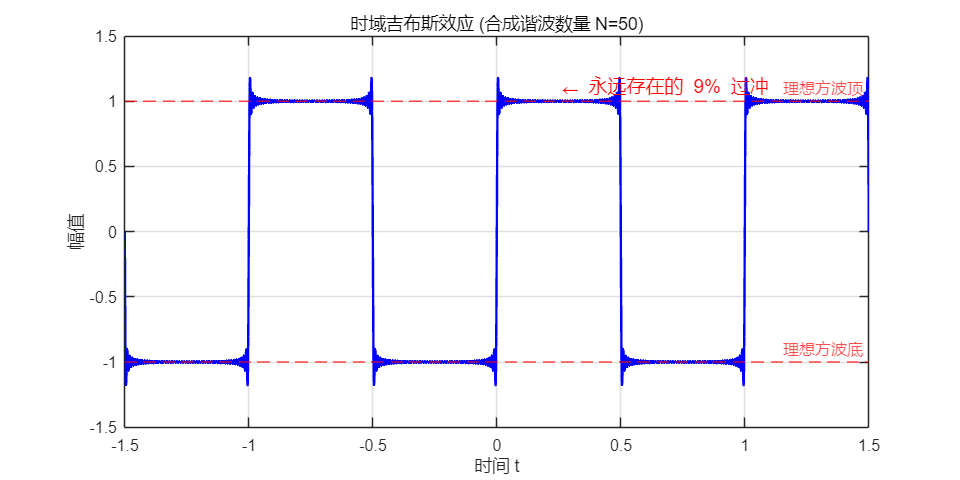

t = linspace(-1.5, 1.5, 10000);
y_approx = zeros(size(t));

% 尝试合成的谐波数量 (你可以修改这个数，比如 5, 20, 100)
% 你会发现，即使 N 很大，尖角依然存在
N_harmonics = 50; 

for k = 1:2:(2*N_harmonics-1)
    y_approx = y_approx + (4/pi) * (1/k) * sin(2*pi*k*t);
end

figure('Color', 'w', 'Position', [100, 100, 800, 400]);
plot(t, y_approx, 'b', 'LineWidth', 1.5); hold on;
yline(1, 'r--', '理想方波顶', 'LineWidth', 1);
yline(-1, 'r--', '理想方波底', 'LineWidth', 1);
title(['时域吉布斯效应 (合成谐波数量 N=', num2str(N_harmonics), ')']);
xlabel('时间 t'); ylabel('幅值');
grid on;
% 标注那个著名的“尖角”
text(0.25, 1.1, '\leftarrow 永远存在的 9% 过冲', 'FontSize', 12, 'Color', 'r');

## 频域表现：滤波器设计中的纹波

比较：直接截断(矩形窗) vs 平滑截断(汉明窗)

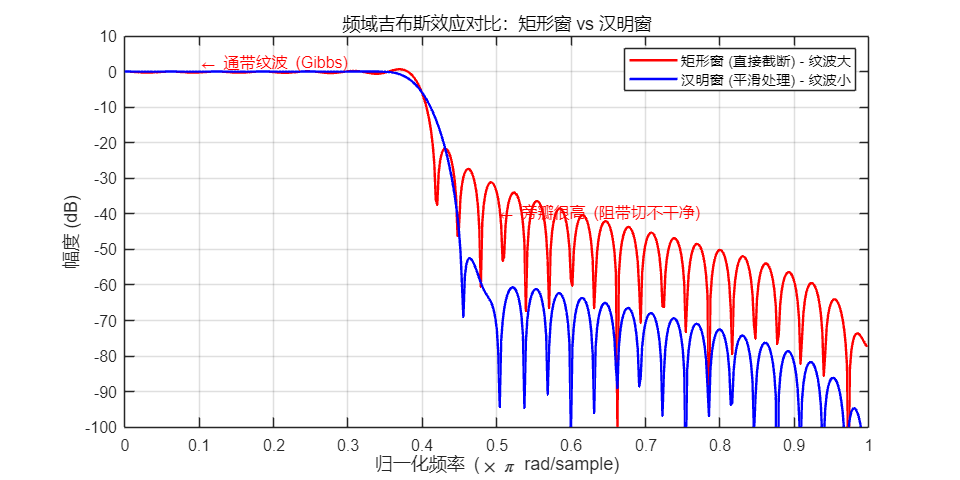

N_tap = 64;   % 滤波器阶数
Wn = 0.4;     % 截止频率

% 1. 使用矩形窗 (Rectangular) -> 吉布斯效应明显
b_rect = fir1(N_tap, Wn, rectwin(N_tap+1));
[h_rect, w] = freqz(b_rect, 1, 512);

% 2. 使用汉明窗 (Hamming) -> 抑制吉布斯效应
b_hamm = fir1(N_tap, Wn, hamming(N_tap+1));
[h_hamm, ~] = freqz(b_hamm, 1, 512);

figure('Color', 'w', 'Position', [100, 550, 800, 400]);
plot(w/pi, 20*log10(abs(h_rect)), 'r', 'LineWidth', 1.5); hold on;
plot(w/pi, 20*log10(abs(h_hamm)), 'b', 'LineWidth', 1.5);
title('频域吉布斯效应对比：矩形窗 vs 汉明窗');
legend('矩形窗 (直接截断) - 纹波大', '汉明窗 (平滑处理) - 纹波小');
xlabel('归一化频率 (\times \pi rad/sample)');
ylabel('幅度 (dB)');
grid on; ylim([-100, 10]);

% 标注关键点
text(0.1, 2, '\leftarrow 通带纹波 (Gibbs)', 'Color', 'r');
text(0.5, -40, '\leftarrow 旁瓣很高 (阻带切不干净)', 'Color', 'r');

## 一个糟糕的滤波器：不考虑吉布斯效应

定义时间轴 我们需要足够高的时间分辨率来展示震荡细节

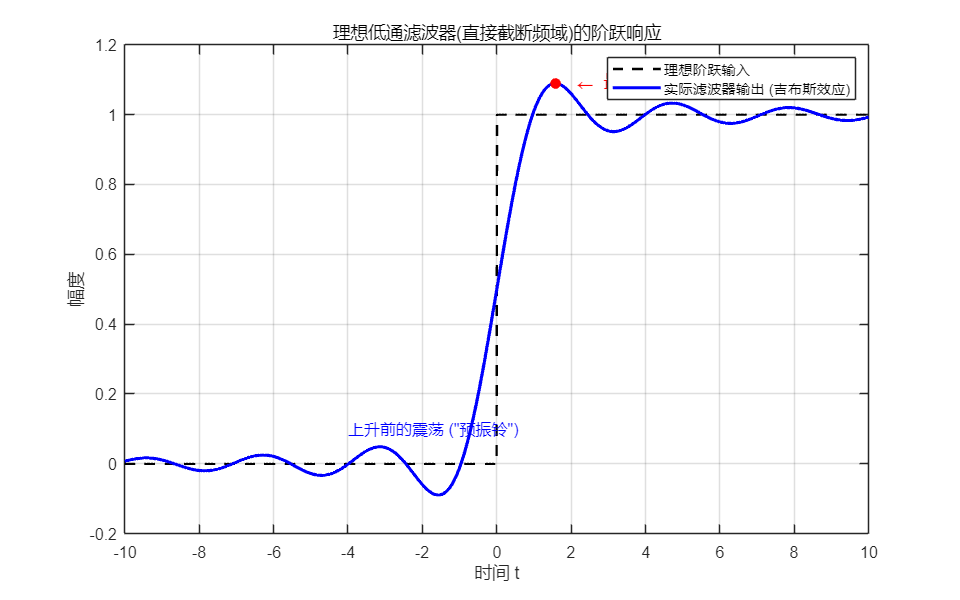

t = linspace(-10, 10, 2000); 

% 定义理想低通滤波器的截止频率 (归一化频率)
% 这个值决定了震荡的快慢
wc = 2; 

% --- 2. 数学原理与计算 ---
% 理想低通滤波器的冲激响应 h(t) 是一个 Sinc 函数：
% h(t) = (wc/pi) * sinc(wc*t/pi) = sin(wc*t)/(pi*t)
%
% 阶跃响应 s(t) 是冲激响应 h(t) 的积分：
% s(t) = ∫ h(tau) d(tau) 从 -∞ 到 t
% 这个积分在数学上称为“正弦积分函数” (Sine Integral, Si(x))
% s(t) = 0.5 + (1/pi) * Si(wc*t)

% 使用 MATLAB 的内置函数 sinint (即 Si(x)) 进行精确计算
% 加上 0.5 是因为阶跃信号是从 0 变为 1，我们需要把中心点抬高到 0.5
y_step_response = 0.5 + (1/pi) * sinint(wc * t);

% 理想输入信号（用于对比）
y_ideal_step = t >= 0;

% --- 3. 绘图可视化 ---
figure('Color', 'w', 'Position', [100, 100, 800, 500]);

% 画出理想的阶跃输入（黑色虚线）
plot(t, y_ideal_step, 'k--', 'LineWidth', 1.5); hold on;

% 画出实际滤波器的输出（蓝色实线）
% 这就是吉布斯效应在时域的真实模样
plot(t, y_step_response, 'b', 'LineWidth', 2);

% --- 4. 标注与美化 ---
title('理想低通滤波器(直接截断频域)的阶跃响应');
xlabel('时间 t');
ylabel('幅度');
grid on;

% 标注关键特征
% 最大过冲点大约在 y = 1.0895 (即 9% 过冲)
max_overshoot = max(y_step_response);
time_of_max = t(y_step_response == max_overshoot);
plot(time_of_max, max_overshoot, 'r.', 'MarkerSize', 20); % 标记最大值点

text(time_of_max + 0.5, max_overshoot, ...
    ['\leftarrow 最大过冲约 ' num2str((max_overshoot-1)*100, '%.1f') '%'], ...
    'Color', 'r', 'FontSize', 12);

% 标注震荡区域
text(-4, 0.1, '上升前的震荡 ("预振铃")', 'Color', 'b');
text(4, 1.1, '上升后的震荡 ("后振铃")', 'Color', 'b');

legend('理想阶跃输入', '实际滤波器输出 (吉布斯效应)');
ylim([-0.2, 1.2]); % 设置纵坐标范围，方便观察